# Calculo del Flux másico de transferencia de masa - Maline

Tabla de datos de Amphlett & Choi (2021)

Estos datos son temperatura ambiente aproximadamente 20°C (293.15 K).

water_content_Mal=[0;0;5;5;5;10;10;10;15;15;20;20;30;30];
coef_extincion_Mal=[0.23595;0.24024;0.01042;0.09262;0.09551;0.01523;0.0065;0.00797;0.01296;0.00579;0.00874;0.00361;0.00829;0.0033];
Temperature=293.15*ones(length(water_content_Mal),1);
concentr_Mal=1./coef_extincion_Mal;
aux=table(Temperature,water_content_Mal,coef_extincion_Mal,concentr_Mal)

aux = 14×4 table
    Temperature    water_content_Mal    coef_extincion_Mal    concentr_Mal
    ___________    _________________    __________________    ____________

      293.15               0                 0.23595             4.2382   
      293.15               0                 0.24024             4.1625   
      293.15               5                 0.01042             95.969   
      293.15               5                 0.09262             10.797   
      293.15               5                 0.09551              10.47   
      293.15              10                 0.01523              65.66   
      293.15              10                  0.0065             153.85   
      293.15              10                 0.00797             125.47   
      293.15              15                 0.01296              77.16   
      293.15         

Cálculo de la densidad

Densidad_Mal= 1.2939+(-0.0012)*water_content_Mal+(-0.0006)*Temperature

Densidad_Mal =     1.1180
    1.1180
    1.1120
    1.1120
    1.1120
    1.1060
    1.1060
    1.1060
    1.1000
    1.1000


Cálculo de la viscosidad

Viscosidad_Eth=zeros(length(water_content_Mal),1);
% Importación de los datos sin outliers para ajuste del modelo
import_train_data=load("Data_Visc_Rel_NoOutliers.mat");
aux1=import_train_data.data1(:,1);
aux2=import_train_data.data1(:,2);
aux3=import_train_data.data1(:,3);
data_train_visc=[aux1 aux2 aux3];
data_train_visc=array2table(data_train_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'});
% Llamado a la función del modelo seleccionado
[regre_visc_rel, ~] = MediumGaussianSVM_Visc_Ethaline(data_train_visc);

% Creacion del vector para predicción
aux_calc_viscosidad=[water_content_Mal Temperature Viscosidad_Eth];
aux_calc_viscosidad=array2table(aux_calc_viscosidad,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'});
% Cálculo de la viscosidad
Viscosidad_Eth=regre_visc_rel.predictFcn(aux_calc_viscosidad)

Viscosidad_Eth =   230.6227
  230.6227
  171.4969
  171.4969
  171.4969
  115.8835
  115.8835
  115.8835
   68.8653
   68.8653


Peso Molecular Promedio

% Datos de pesos moleculares como 2 componentes (Suma-->xiMi)
PM_Reline=87.92;
PM_Ethaline=91.22;
PM_Maline=136.85;
PM_water=18.02;
% Conversión de base de cálculo másica a molar
moles_Agua=water_content_Mal/PM_water;
moles_Maline=(100-water_content_Mal)/PM_Maline;
moles_totales=moles_Agua+moles_Maline;
fraccion_molar_agua=moles_Agua./moles_totales;
fraccion_molar_Maline=moles_Maline./moles_totales;
% Cálculo del peso molecular de la mezcla
PM_Mezcla=fraccion_molar_agua*PM_water+fraccion_molar_Maline*PM_Maline

PM_Mezcla =   136.8500
  136.8500
  102.9166
  102.9166
  102.9166
   82.4679
   82.4679
   82.4679
   68.7982
   68.7982


Volumen molar

Vol_molar=PM_Mezcla./Densidad_Mal

Vol_molar =   122.4050
  122.4050
   92.5501
   92.5501
   92.5501
   74.5634
   74.5634
   74.5634
   62.5432
   62.5432


Difusividad

fact_aso=1; % INPUT Factor de asociacion chi desde 1 hasta 2.6
% Cálculo del coeficiente de difusividad
Diff=(7.4e-8)*((fact_aso.^0.5*PM_Mezcla.^0.5.*Temperature)./(Viscosidad_Eth.*Vol_molar.^0.6))

Diff = 	1.0e+-4 *

    0.0006
    0.0006
    0.0008
    0.0008
    0.0008
    0.0013
    0.0013
    0.0013
    0.0022
    0.0022


Flux 

Flux=Diff.*concentr_Mal

Flux =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


aux=table(Densidad_Mal, Viscosidad_Eth, PM_Mezcla, Vol_molar, Diff, Flux)

aux = 14×6 table
    Densidad_Mal    Viscosidad_Eth    PM_Mezcla    Vol_molar       Diff          Flux   
    ____________    ______________    _________    _________    __________    __________

       1.118            230.62         136.85        122.4      6.1498e-08    2.6064e-07
       1.118            230.62         136.85        122.4      6.1498e-08    2.5599e-07
       1.112             171.5         102.92        92.55      8.4817e-08    8.1398e-06
       1.112             171.5         102.92        92.55      8.4817e-08    9.1575e-07
       1.112             171.5         102.92        92.55      8.4817e-08    8.8804e-07
       1.106            115.88         82.468       74.563      1.2792e-07     8.399e-06
       1.106            115.88         82.468       74.563      1.

Sensibilidades de factor de asociación chi desde 1 hasta 2.6

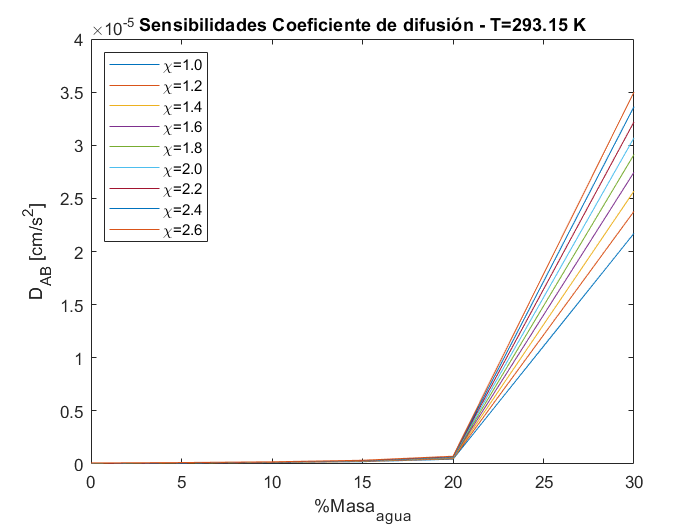

j=1;
for fact_aso=1:0.2:2.6
    Diff_sens(:,j)=(7.4e-8)*((fact_aso.^0.5*PM_Mezcla.^0.5.*Temperature)./(Viscosidad_Eth.*Vol_molar.^0.6));
    plot(water_content_Mal,Diff_sens(:,j)), hold on
    j=j+1; 
end
title('Sensibilidades Coeficiente de difusión - T=293.15 K')
xlabel('%Masa_a_g_u_a'), ylabel('D_A_B [cm/s^2]')
legend('\chi=1.0','\chi=1.2','\chi=1.4','\chi=1.6','\chi=1.8','\chi=2.0','\chi=2.2','\chi=2.4','\chi=2.6','Location','northwest')
hold off

Flux=Diff_sens.*concentr_Mal

Flux =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001


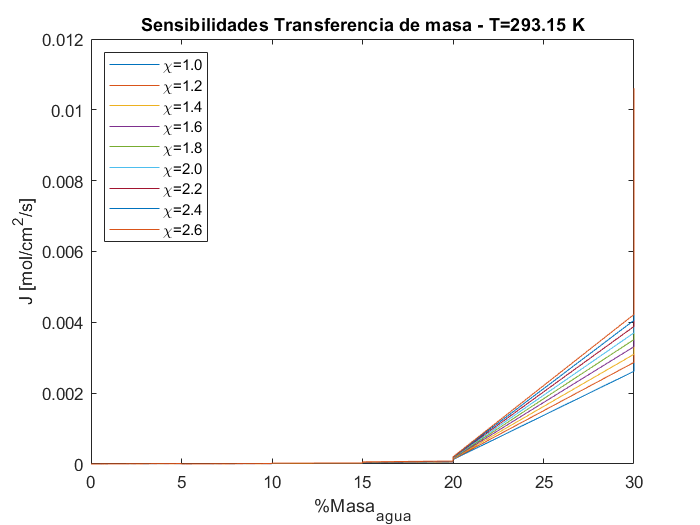


for k=1:9
    plot(water_content_Mal,Flux(:,k)), hold on 
end
title('Sensibilidades Transferencia de masa - T=293.15 K')
xlabel('%Masa_a_g_u_a'), ylabel('J [mol/cm^2/s]')
legend('\chi=1.0','\chi=1.2','\chi=1.4','\chi=1.6','\chi=1.8','\chi=2.0','\chi=2.2','\chi=2.4','\chi=2.6','Location','northwest')
hold off